>>> Declarando variables...ok
>>>>> Obteniendo la zona de estudio
>>>>> Analizando 2 archivos
>>>>> Obteniendo información de archivos sobre fechas ... 
>>>>> Analizando 1042 archivos
>>> Cargando área de estudio
Total de imágenes: 519


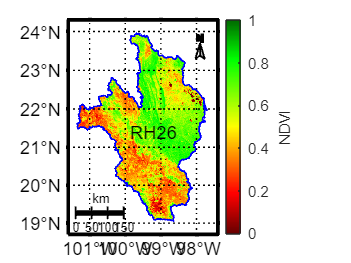

ae = exist("arr_ndvi","var");
if ae == 0  %si no existe, cargar la infromación
    new_cargar_informacion
end

## Filtrar información

% Declaraciones
% Los años que se desean consultar
meses = 1:12;
anios = 2000:2022;

% Arreglo donde se almacenara el promedio de NDVI por año
tabla_promedio =zeros(length(anios),length(meses));
tabla_desvEst =zeros(length(anios),length(meses));

tabla_promedio_lf =zeros(length(anios),length(meses));
tabla_desvEst_lf =zeros(length(anios),length(meses));

tabla_promedio_sgf =zeros(length(anios),length(meses));
tabla_desvEst_sgf =zeros(length(anios),length(meses));


%generar las etiquetas de año y estación
%lbl_meses = ["Enero","Febrero","Marzo","Abril","Mayo","Junio","Julio","Agosto","Septiembre","Octubre","Noviembre","Diciembre"];
lbl_meses = ["Enero","","","","","","","","","","",""];

lbl_ejex = string(1: length(anios)*length(meses));
a=1;
for i=anios
    for j=meses
        if j == 1 %|| j == 3 || j== 6 || j==9 
            lbl_ejex (a) = strcat( lbl_meses(j)," ",""+i);
        else
            lbl_ejex (a)="";
        end
        a=a+1;
    end
end

x=1;   
bp=waitbar(0,'Filtrando información'); 

for y= 1:length(anios)
    waitbar(y/length(anios),bp);

    for m = 1:length(meses)
        tmp =  find(  info_hdf.anio == anios(y) & info_hdf.mes == meses(m)  );
    
        if( isempty (tmp))
            continue;
        end
                 
        tabla_promedio_lf(y,m) = mean(arr_ndvi_lf (:,:,tmp),"all","omitnan");
        tabla_desvEst_lf(y,m) = std(arr_ndvi_lf (:,:,tmp),0,"all","omitnan");
       
        tabla_promedio(y,m) = mean(arr_ndvi (:,:,tmp),"all","omitnan");
        tabla_desvEst(y,m) = std(arr_ndvi (:,:,tmp),0,"all","omitnan");

        tabla_promedio_sgf(y,m) = mean(arr_ndvi_sgf (:,:,tmp),"all","omitnan");
        tabla_desvEst_sgf(y,m) = std(arr_ndvi_sgf (:,:,tmp),0,"all","omitnan");
        
    end
    waitbar(y/length(anios),bp,sprintf('Año: (%4d) ',anios(y)));

end
close(bp); 


### 4.- Usar los datos obtenidos 

Mostrar el promedio por mes de cada año

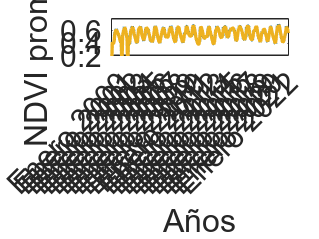

figure;

linea_tiempo_promedio = reshape(tabla_promedio',[],1);
linea_tiempo_promedio_lf = reshape(tabla_promedio_lf',[],1);
linea_tiempo_promedio_sgf = reshape(tabla_promedio_sgf',[],1);

linea_tiempo_desv = reshape(tabla_desvEst_lf',[],1);

plot(linea_tiempo_promedio,'LineWidth',2);
%title('NDVI promedio x estación');
xlabel('Años','FontSize',18);
xticks(1:length(linea_tiempo_promedio));
xticklabels(lbl_ejex);
ylabel('NDVI promedio','FontSize',18);
xlim([0 (length(linea_tiempo_promedio)+1)]);
ylim([0.2 0.8]);
xtickangle(45);
ax = gca;
ax.FontSize=18; 

hold on
plot(linea_tiempo_promedio_lf,'LineWidth',1,'LineStyle','--');
plot(linea_tiempo_promedio_sgf,'LineWidth',2);
hold off
% hold on
% 
% er=errorbar(1:length(linea_tiempo_promedio),linea_tiempo_promedio,linea_tiempo_desv); 
% er.Color = [0 0 0];                            
% er.LineStyle = 'none';  
% 
% hold off

exportgraphics(gca,"img/new_g_promedio_x_año_mes_lt.png",'Resolution',300) 